% Expand in the Fourier series a periodic function given 
% on the half-period [0;2] by the equation f(x)=x-1/2*x^2.

clear
syms x real;
syms pi;
f=x-1/2*x^2;
L=2;

% 1)
a0=int(x-1/2*x^2,x,0,2)

$$a0 = \frac{2}{3}$$

% 2/3
syms m integer;
assume(m>=1)
a(m)=(2/L)*int(f*cos(m*pi*x/L),x,0,2)

$$a(m) = \frac{8\,\sin\left(\pi \,m\right)}{m^{3}\,\pi^{3}}-\frac{4\,\cos\left(\pi \,m\right)}{m^{2}\,\pi^{2}}-\frac{4}{m^{2}\,\pi^{2}}$$

% (8*sin(pi*m))/(m^3*pi^3) - (4*cos(pi*m))/(m^2*pi^2) - 4/(m^2*pi^2)
%     =0                          (-1)^m
a(m)=simplify(subs(a(m),[sin(pi*m) cos(pi*m)],[0 (-1)^m]))

$$a(m) = -\frac{4\,\left({\left(-1\right)}^{m}+1\right)}{m^{2}\,\pi^{2}}$$

% -(4*((-1)^m + 1))/(m^2*pi^2)

% a(m)=-((-1)^m+1)*(4/(m^2*pi^2))
af(m)=a(m)*cos(m*pi*x/L)

$$af(m) = -\frac{4\,\cos\left(\frac{\pi \,m\,x}{2}\right)\,\left({\left(-1\right)}^{m}+1\right)}{m^{2}\,\pi^{2}}$$

% -(4*cos((pi*m*x)/2)*((-1)^m + 1))/(m^2*pi^2)

b(m)=(2/L)*int(f*sin(m*pi*x/L),x,0,2);
% (16*sin((pi*m)/2)^2)/(m^3*pi^3) - (4*sin(pi*m))/(m^2*pi^2)
%        =0                               =0
b(m)=simplify(subs(b(m),[sin(pi*m) sin((pi*m)/2)^2],[0 (1-(-1)^m)/2]))

$$b(m) = -\frac{8\,{\left(-1\right)}^{m}-8}{m^{3}\,\pi^{3}}$$


b(m)=sym(0)

$$b(m) = 0$$

bf(m)=b(m)*sin(m*pi*x/L)

$$bf(m) = 0$$

% 0
abf(m)=af(m)+bf(m)

$$abf(m) = -\frac{4\,\cos\left(\frac{\pi \,m\,x}{2}\right)\,\left({\left(-1\right)}^{m}+1\right)}{m^{2}\,\pi^{2}}$$

% -(4*cos((pi*m*x)/2)*((-1)^m + 1))/(m^2*pi^2)
fplot(f,[0 L]);
hold on;
grid on;

f1=a0/2

$$f1 = \frac{1}{3}$$

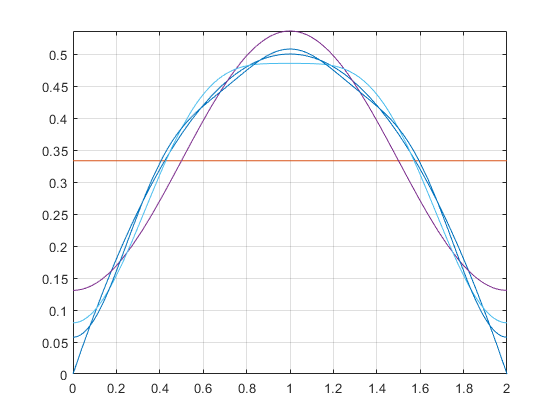

for m=1:7
    m1(m)=m;
    a1(m)=a(m);
    b1(m)=b(m);
    abf1(m)=abf(m);
    f1=f1+abf(m);
    fplot(f1,[0 L]);
    grid on;
end
hold off


disp(f1)

$$\frac{1}{3}-\frac{\cos\left(2\,\pi \,x\right)}{2\,\pi^{2}}-\frac{2\,\cos\left(3\,\pi \,x\right)}{9\,\pi^{2}}-\frac{2\,\cos\left(\pi \,x\right)}{\pi^{2}}$$

% 1/3 - cos(2*pi*x)/(2*pi^2) - (2*cos(3*pi*x))/(9*pi^2) - (2*cos(pi*x))/pi^2

a0/2

$$ans = \frac{1}{3}$$

% 1/3
ft=[m1;a1;b1;abf1];
ft'

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 2 & -\frac{2}{\pi^{2}} & 0 & -\frac{2\,\cos\left(\pi \,x\right)}{\pi^{2}}\\ 3 & 0 & 0 & 0\\ 4 & -\frac{1}{2\,\pi^{2}} & 0 & -\frac{\cos\left(2\,\pi \,x\right)}{2\,\pi^{2}}\\ 5 & 0 & 0 & 0\\ 6 & -\frac{2}{9\,\pi^{2}} & 0 & -\frac{2\,\cos\left(3\,\pi \,x\right)}{9\,\pi^{2}}\\ 7 & 0 & 0 & 0 \end{array}\right)$$

% [ 1,           0, 0,                         0]
% [ 2,     -2/pi^2, 0,       -(2*cos(pi*x))/pi^2]
% [ 3,           0, 0,                         0]
% [ 4, -1/(2*pi^2), 0,     -cos(2*pi*x)/(2*pi^2)]
% [ 5,           0, 0,                         0]
% [ 6, -2/(9*pi^2), 0, -(2*cos(3*pi*x))/(9*pi^2)]
% [ 7,           0, 0,                         0]

syms m k;
abf2(k)=subs(abf(m),m,2*k)

$$abf2(k) = -\frac{\cos\left(\pi \,k\,x\right)\,\left({\left(-1\right)}^{2\,k}+1\right)}{k^{2}\,\pi^{2}}$$

% -(cos(pi*k*x)*((-1)^(2*k) + 1))/(k^2*pi^2)
%                 =1
abf2(k)=-(2*cos(pi*k*x))/(k^2*pi^2)

$$abf2(k) = -\frac{2\,\cos\left(\pi \,k\,x\right)}{k^{2}\,\pi^{2}}$$


for k=1:3
    k3(k)=k;
    abf3(k)=abf2(k);
end
ft2=[k3;abf3]

$$ft2 = \left(\begin{array}{ccc} 1 & 2 & 3\\ -\frac{2\,\cos\left(\pi \,x\right)}{\pi^{2}} & -\frac{\cos\left(2\,\pi \,x\right)}{2\,\pi^{2}} & -\frac{2\,\cos\left(3\,\pi \,x\right)}{9\,\pi^{2}} \end{array}\right)$$

ft2'

$$ans = \left(\begin{array}{cc} 1 & -\frac{2\,\cos\left(\pi \,x\right)}{\pi^{2}}\\ 2 & -\frac{\cos\left(2\,\pi \,x\right)}{2\,\pi^{2}}\\ 3 & -\frac{2\,\cos\left(3\,\pi \,x\right)}{9\,\pi^{2}} \end{array}\right)$$

% [ 1,       -(2*cos(pi*x))/pi^2]
% [ 2,     -cos(2*pi*x)/(2*pi^2)]
% [ 3, -(2*cos(3*pi*x))/(9*pi^2)]